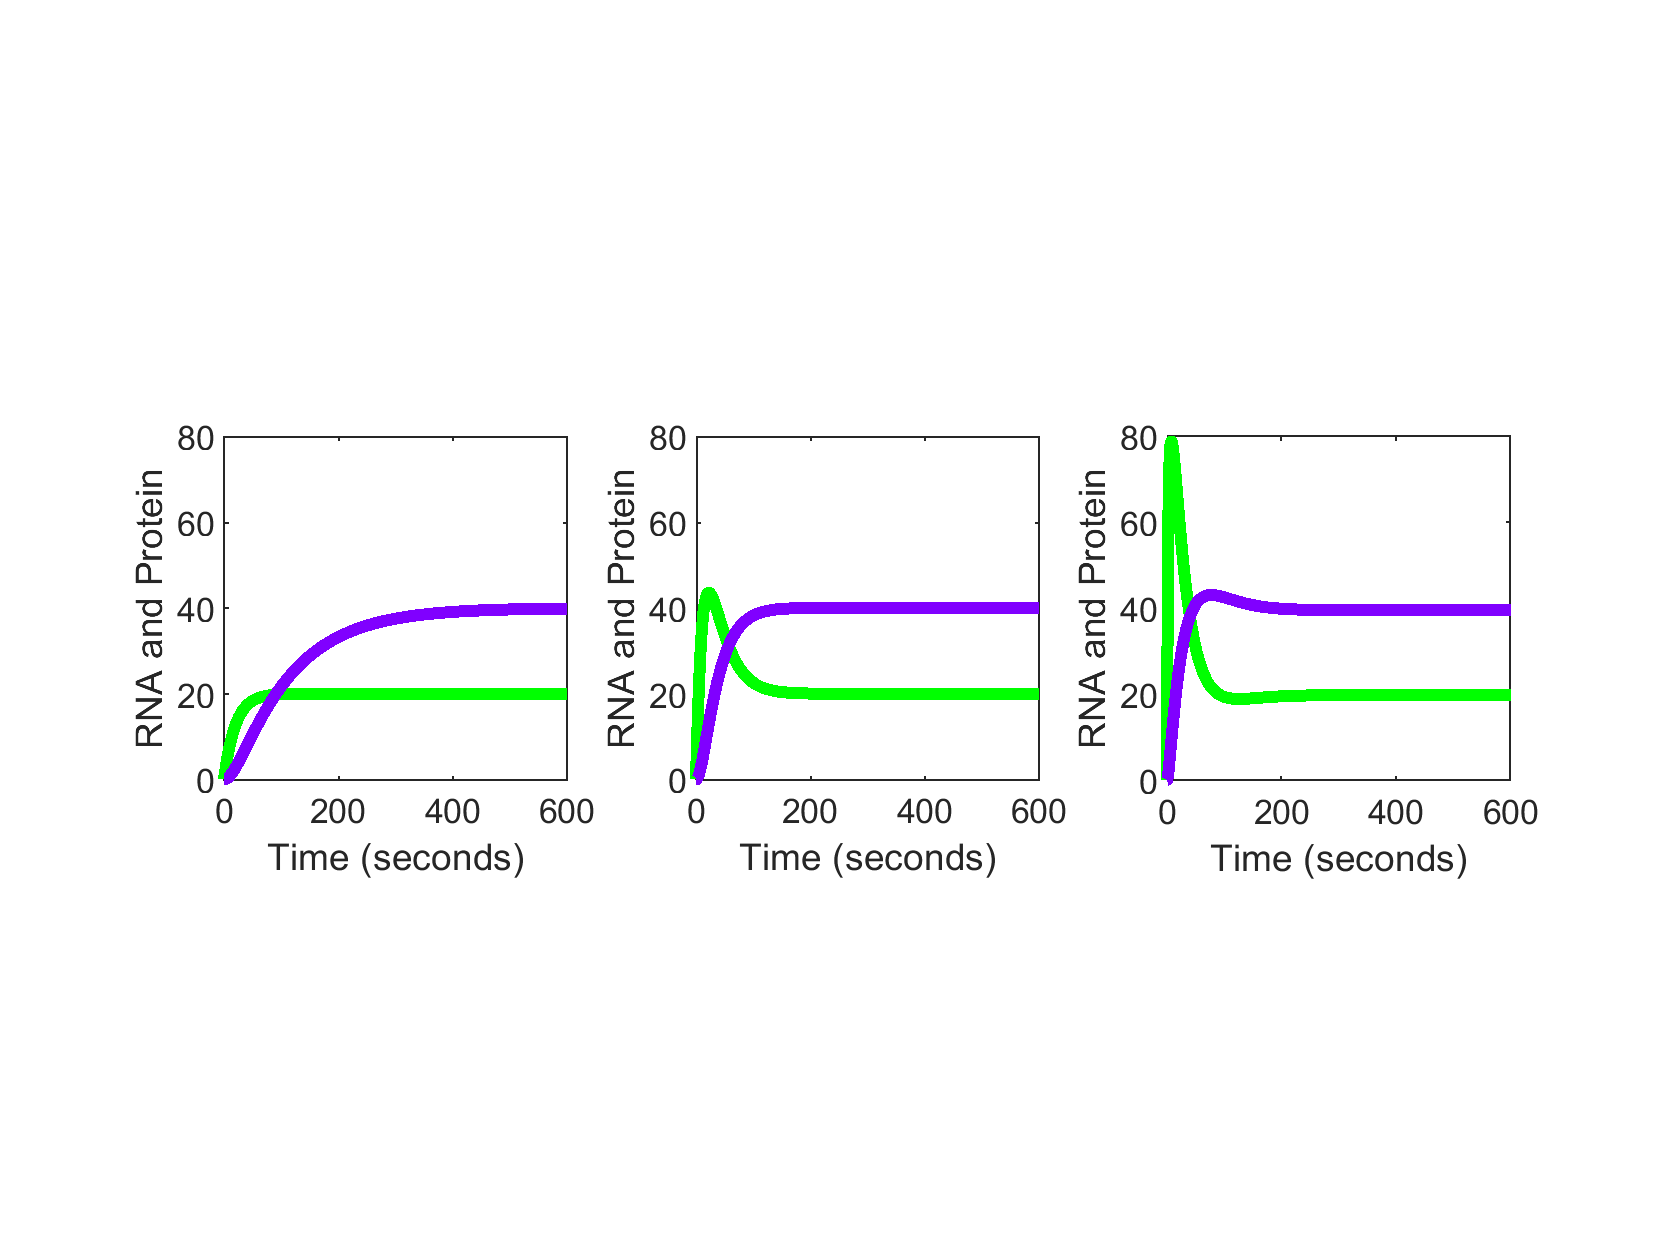

%% 3.0 ----- (DIRECT) NEGATIVE FEEDBACK -----

%gamma_ma = 1;
delta_ma = 0.05;
gamma_pa = 0.02;
delta_pa = 0.01;

params{1}.Kaa       = 0;
params{1}.gamma_ma0 = 1;

params{2}.Kaa       = 0.1;
params{2}.gamma_ma0 = 5;

params{3}.Kaa       = 1;
params{3}.gamma_ma0 = 40;

figure; clf; hold on; box on;

for iParam = 1:numel(params)

    Kaa = params{iParam}.Kaa; % Strength of inhibition of A by A 
    gamma_ma0 = params{iParam}.gamma_ma0; % Baseline production rate mRNA for A
    
    gamma_ma =@(pa) gamma_ma0./(1+Kaa*pa);

    dmadt =@(ma,pa,mb,pb,t) +gamma_ma(pa) - delta_ma*ma;
    dpadt =@(ma,pa,mb,pb,t) +gamma_pa*ma - delta_pa*pa;

    dxdt = @(t,x)[dmadt(x(1),x(2),t);
                  dpadt(x(1),x(2),t)];

    initialCondition = [0,0];

    [T, X] = ode45(dxdt, [0.0,600], initialCondition);

    subplot(1,numel(params),iParam); hold on; box on;
    axis square;
    set(gca,'xlim',[0,600], 'ylim',[0,80]);
    ylabel('RNA and Protein')   
    xlabel('Time (seconds)')
    plot(T,X(:,1),'-g', 'linewidth', 3); % red for RNA
    plot(T,X(:,2),'-', 'color', [0.5 0 1],'linewidth', 3); % purple

end

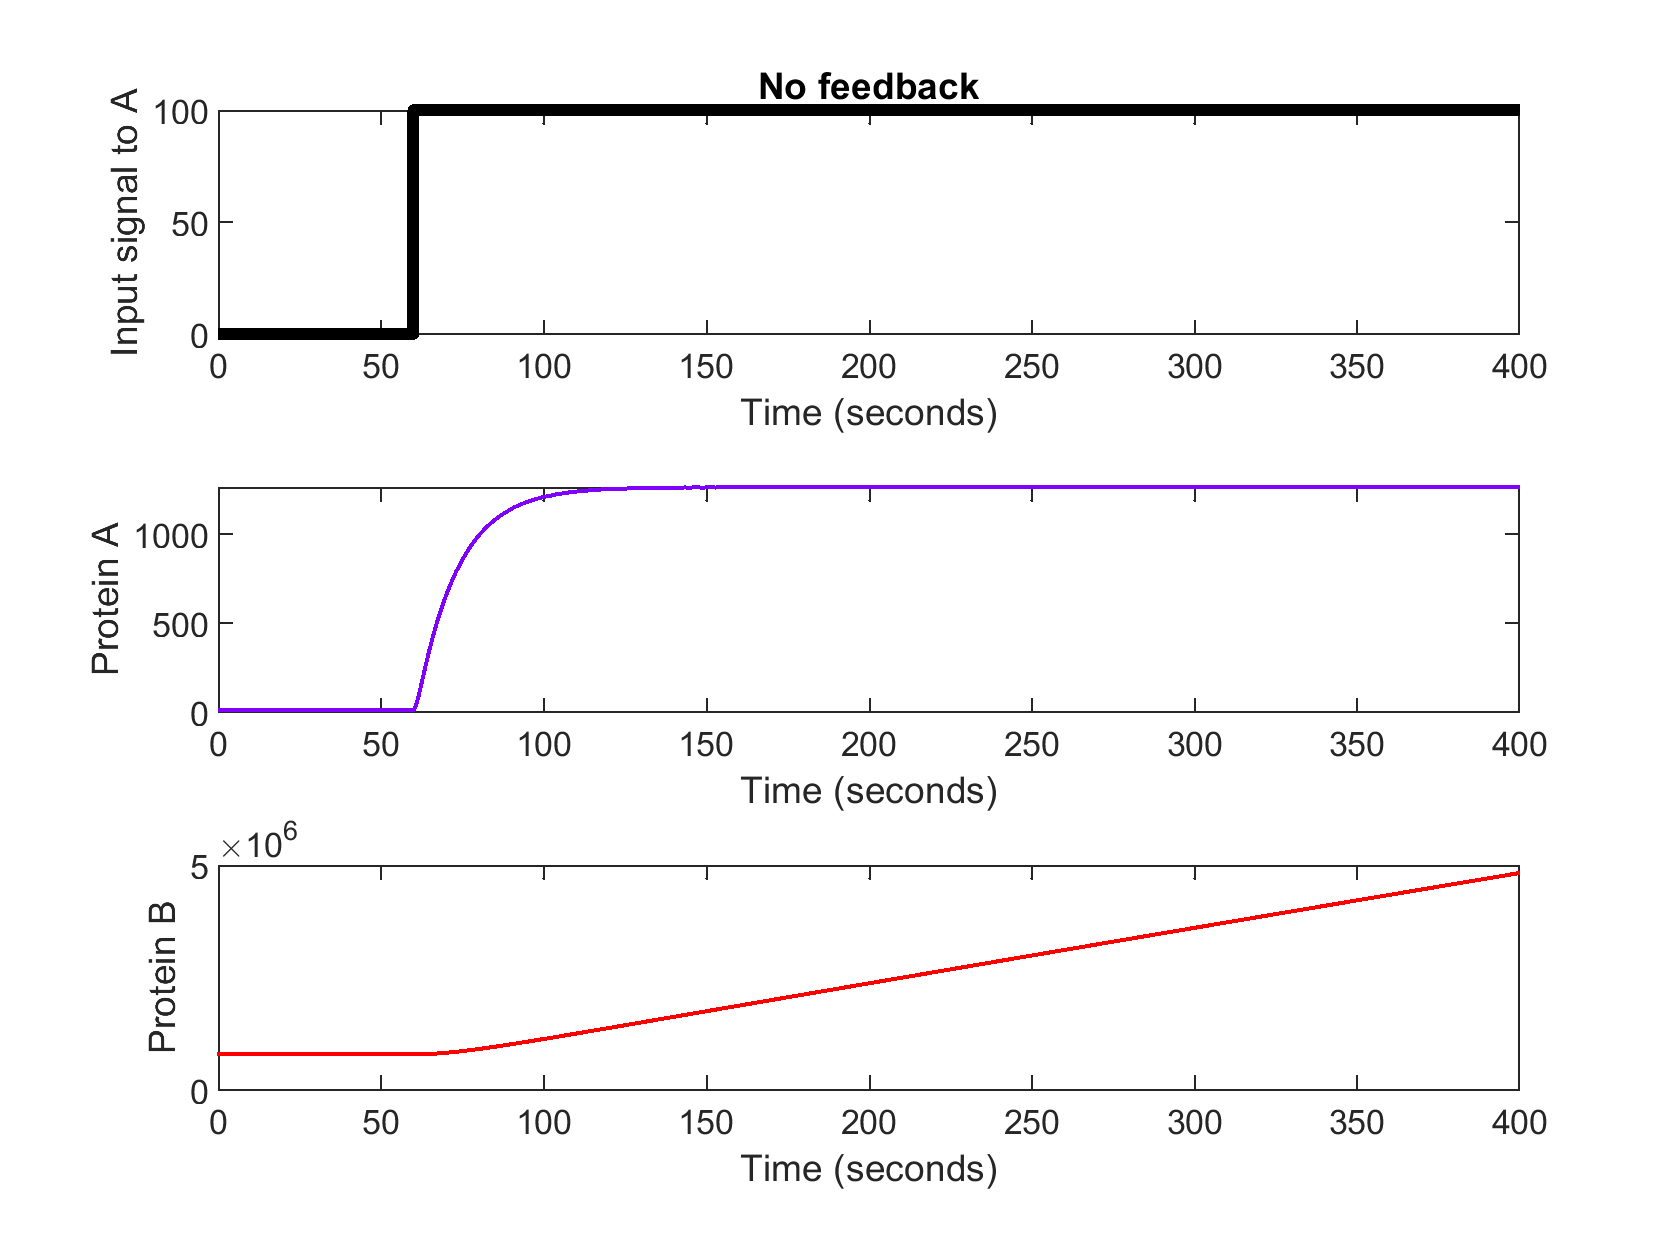

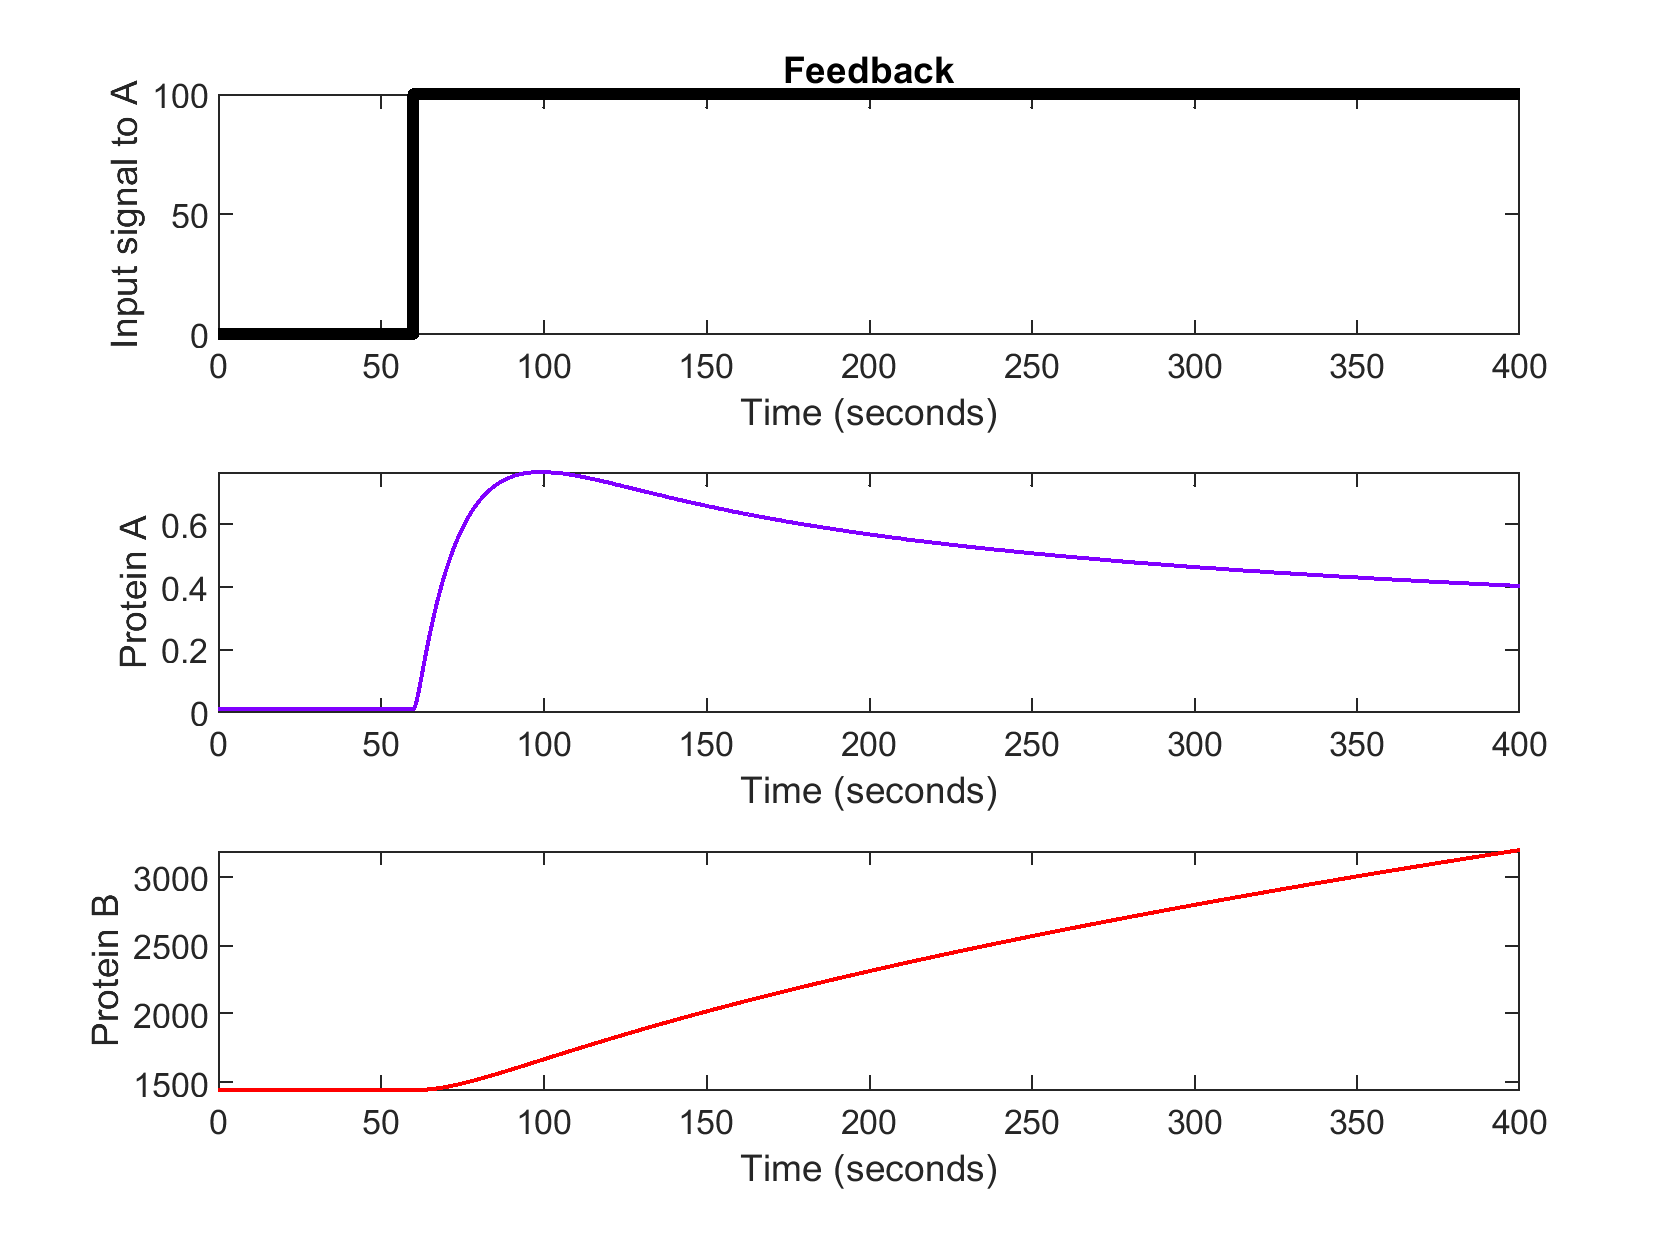

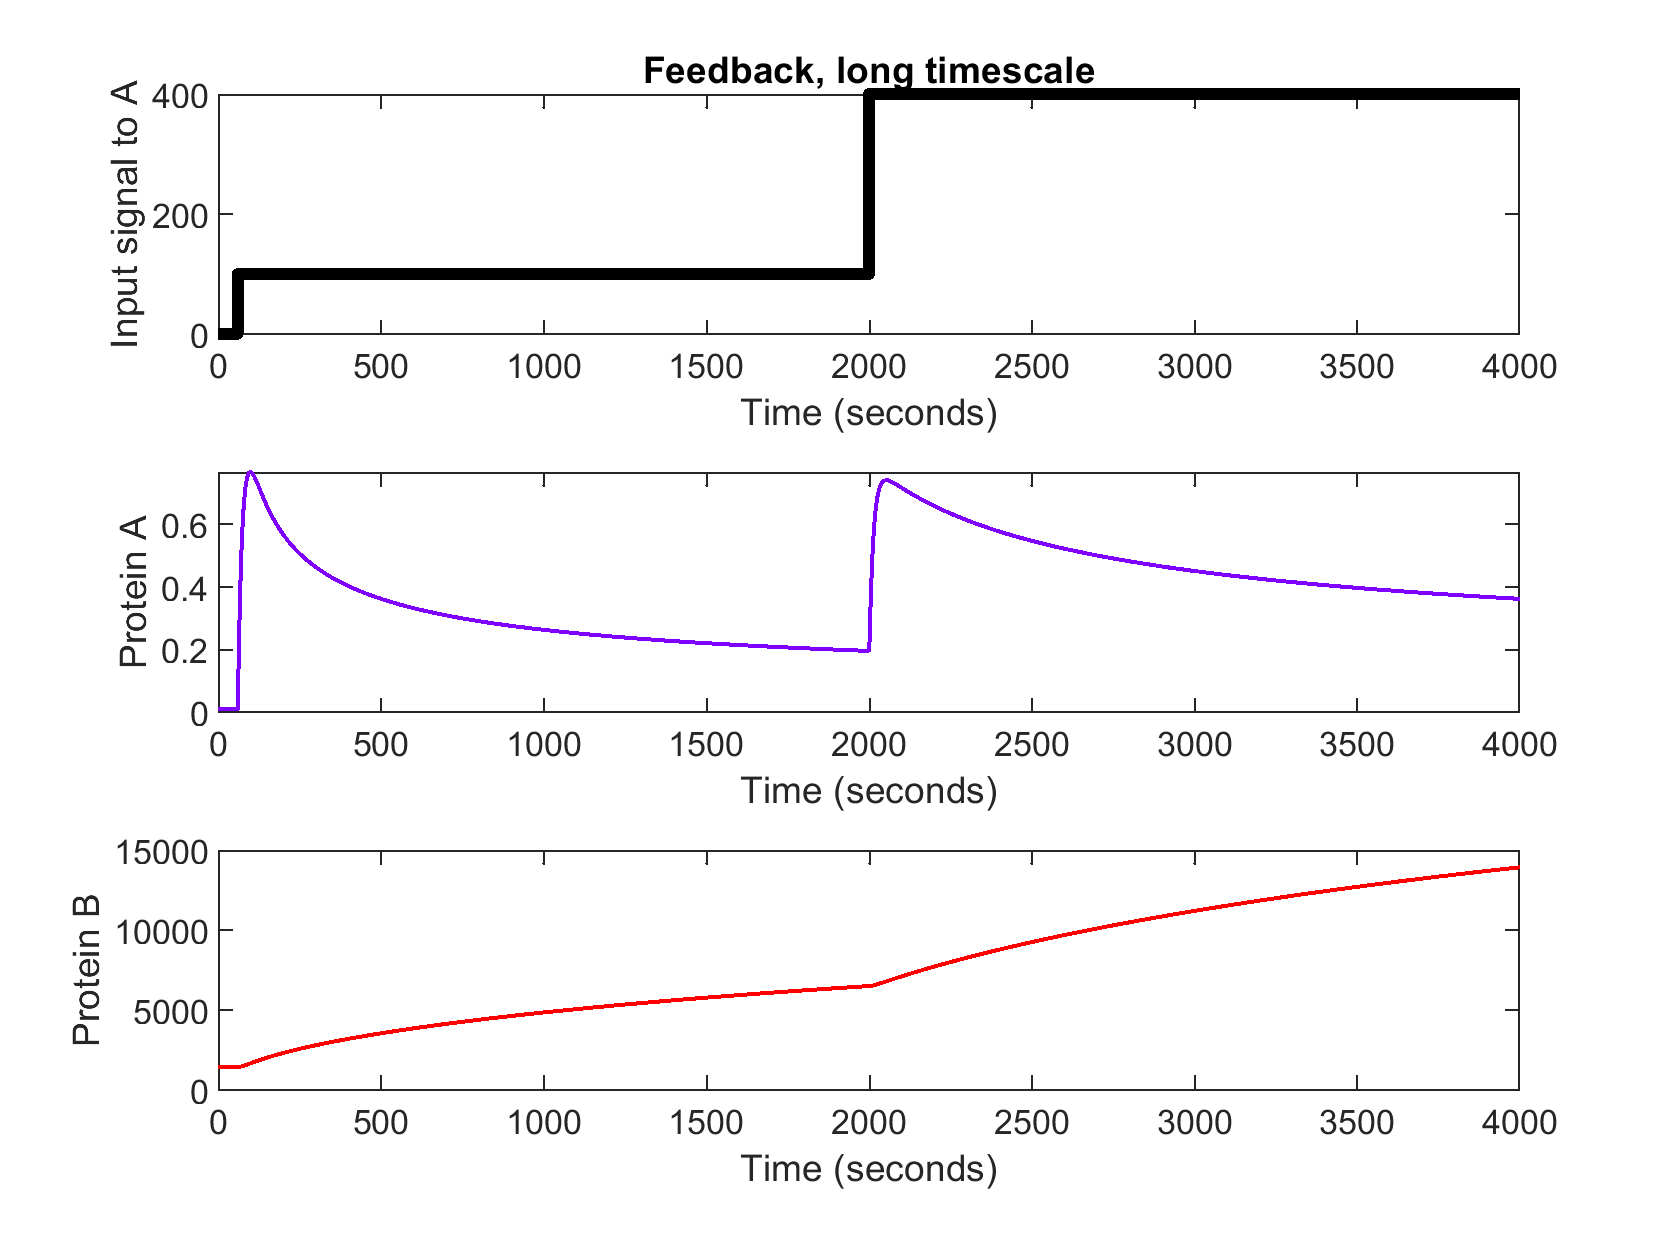


%% 4.0 ----- INDIRECT NEGATIVE FEEDBACK -----

delta_ma = 0.08;
gamma_pa = 1;
delta_pa = 1;

delta_mb = 1e-4;
gamma_pb = 1;
delta_pb = 1;

params{1}.title = 'No feedback';
params{1}.Kba   = 0;
params{1}.Kab   = 1e4;
params{1}.tMax  = 400;

params{2}.title = 'Feedback';
params{2}.Kba   = 1.0;
params{2}.Kab   = 1e4;
params{2}.tMax  = 400;

params{3}.title = 'Feedback, long timescale';
params{3}.Kba   = 1.0;
params{3}.Kab   = 1e4;
params{3}.tMax  = 4000;

% an input signal, e.g., externally-induced production
i = @(t) 0*(t<60) + 100*(t>60) + 300*(t>2000);

for iParam = 1:numel(params)

    Kba = params{iParam}.Kba; % Strength (IC50^-1) of inhibition of A by B 
    gamma_ma =@(pb,t) 1./(1+Kba*pb).*(1.0+i(t));
    
    Kab = params{iParam}.Kab; % Strength (EC50^-1) of activation of B by A 
    gamma_mb =@(pa) 1e-3.*(1+Kab*pa);

    dmadt =@(ma,pa,mb,pb,t) +gamma_ma(pb,t) - delta_ma*ma;
    dpadt =@(ma,pa,mb,pb,t) +gamma_pa*ma - delta_pa*pa;

    dmbdt =@(ma,pa,mb,pb,t) +gamma_mb(pa) - delta_mb*mb;
    dpbdt =@(ma,pa,mb,pb,t) +gamma_pb*mb - delta_pb*pb;

    dxdt = @(t,x)[dmadt(x(1),x(2),x(3),x(4),t);
                  dpadt(x(1),x(2),x(3),x(4),t);
                  dmbdt(x(1),x(2),x(3),x(4),t);
                  dpbdt(x(1),x(2),x(3),x(4),t)];

    initialCondition = [20,20,0,0];
    tMax = params{iParam}.tMax;

    [T, X] = ode45(dxdt, [-10000.0,tMax], initialCondition);

    %figure(40+iParam); clf; 
    figure(); clf; 
    subplot(3,1,1);hold on; box on;
    title(params{iParam}.title)

    plot(T,i(T),'-k', 'linewidth',3); % purple
    ylabel('Input signal to A')
    xlabel('Time (seconds)')
    set(gca,'xlim',[0,tMax]);

    subplot(3,1,2);hold on; box on;
    plot(T,X(:,2),'-', 'color', [0.5 0 1], 'linewidth',1); % purple
    ylabel('Protein A')
    xlabel('Time (seconds)')
    set(gca,'xlim',[0,tMax]);

    subplot(3,1,3);hold on; box on;
    plot(T,X(:,3),'-r', 'linewidth',1); % red for RNA
    ylabel('Protein B')
    xlabel('Time (seconds)')
    set(gca,'xlim',[0,tMax]);

end

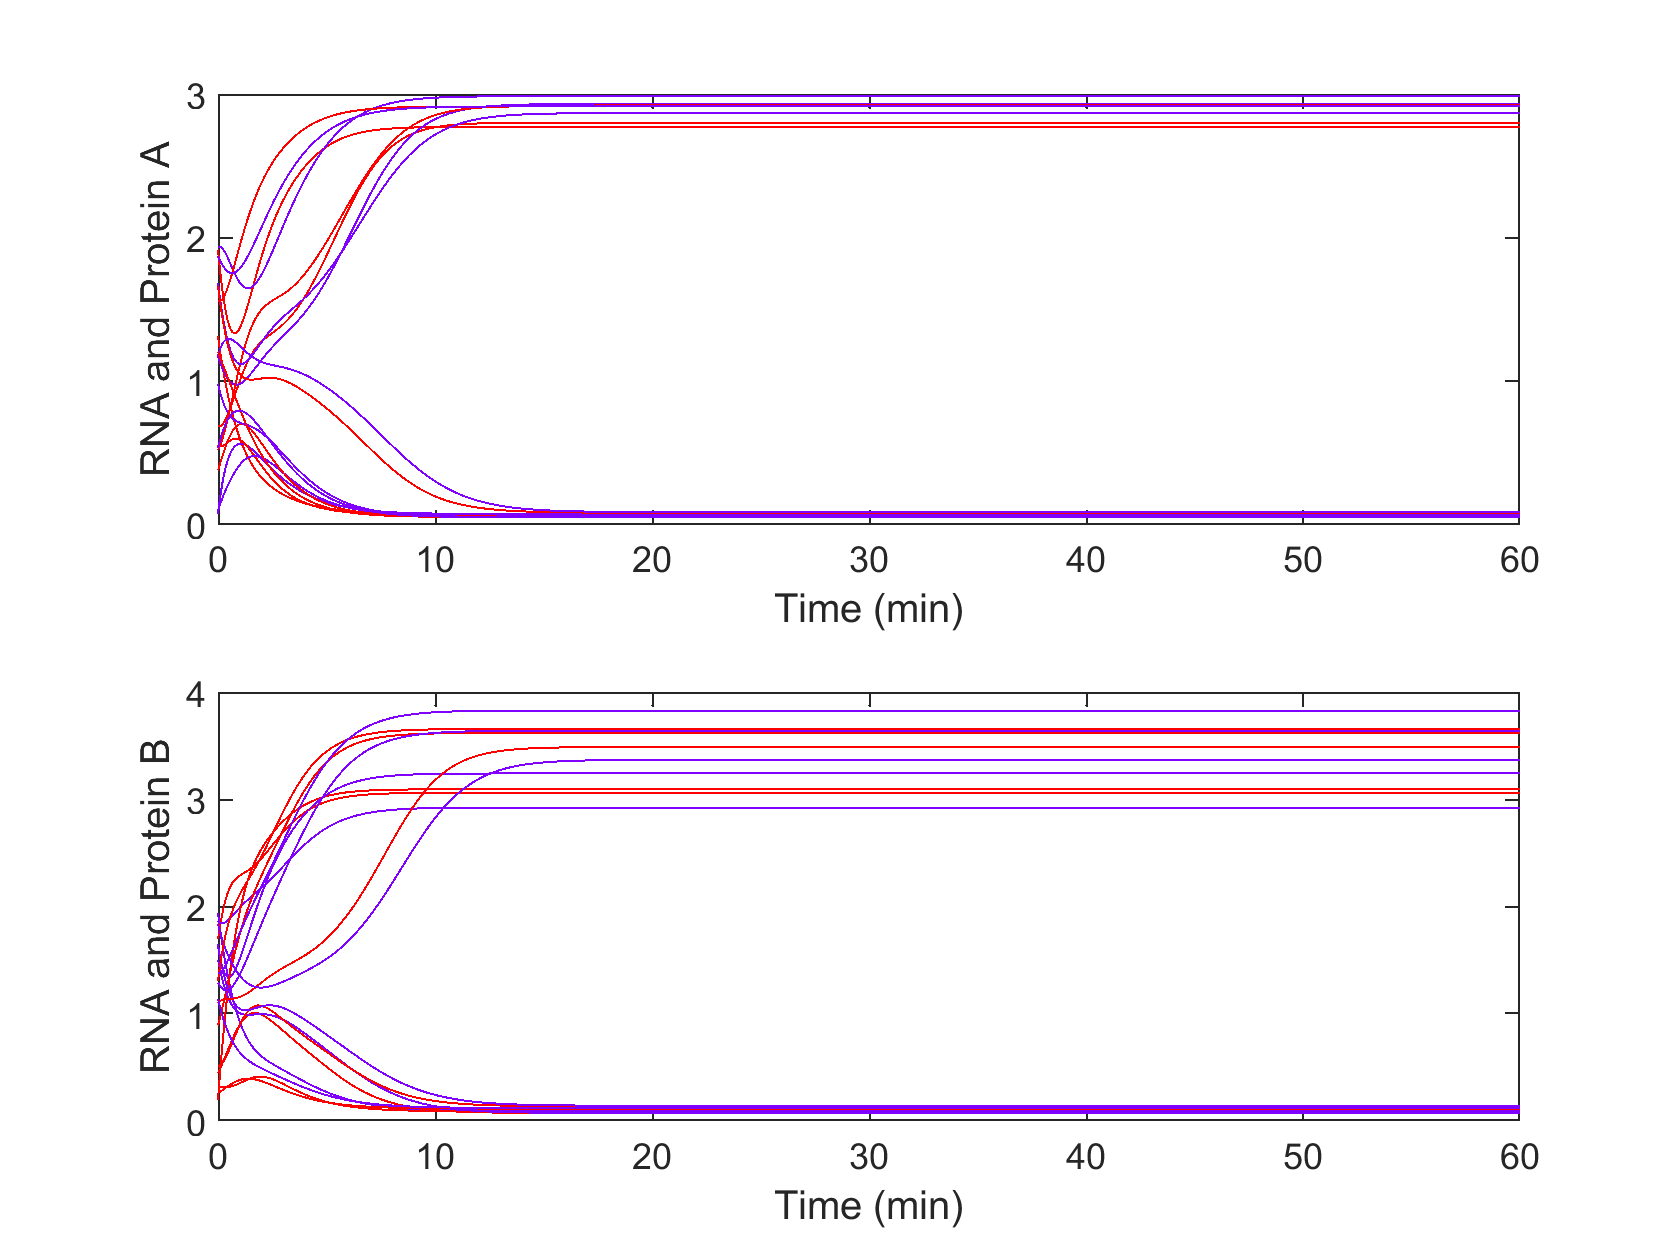

%% 5.0 ----- DOUBLE NEGATIVE FEEDBACK -----

noisiness = 0.1;
noisiness2 = 0.1;

figure(); clf; 

numRuns = 1000;
storage_A = zeros(1,numRuns);
storage_B = zeros(1,numRuns);

          
for iRun = 1:numRuns
                    
    delta_ma = 1*(1+noisiness*rand());
    gamma_pa = 1*(1+noisiness*rand());
    delta_pa = 1*(1+noisiness*rand());
    
    delta_mb = 1*(1+noisiness*randn());
    gamma_pb = 1*(1+noisiness*rand());
    delta_pb = 1*(1+noisiness*rand());
    
    Kba = 1*(1+noisiness2*randn()); % Strength (IC50^-1) of inhibition of A by B
    Kaa = 0;
    gamma_ma =@(pb) 3./(1+abs(Kba*pb).^3);
    
    Kab = 1*(1+noisiness2*randn()); % Strength (IC50) of inhibition of B by A
    Kbb = 0;
    gamma_mb =@(pa) 3./(1+abs(Kab*pa).^3);

    dmadt =@(ma,pa,mb,pb,t) +gamma_ma(pb) - delta_ma*ma;
    dpadt =@(ma,pa,mb,pb,t) +gamma_pa*ma - delta_pa*pa;
    
    dmbdt =@(ma,pa,mb,pb,t) +gamma_mb(pa) - delta_mb*mb;
    dpbdt =@(ma,pa,mb,pb,t) +gamma_pb*mb - delta_pb*pb;

    dxdt = @(t,x)[dmadt(x(1),x(2),x(3),x(4),t);
                  dpadt(x(1),x(2),x(3),x(4),t);
                  dmbdt(x(1),x(2),x(3),x(4),t);
                  dpbdt(x(1),x(2),x(3),x(4),t)];
    
    
    initialCondition = 2*rand(4,1);
    

    [T, X] = ode45(dxdt, [0.0,60], initialCondition);

    if iRun<10
        subplot(2,1,1);hold on; box on;
        plot(T,X(:,1),'-r'); % red for RNA
        plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple
        ylabel('RNA and Protein A')
        xlabel('Time (min)')

        subplot(2,1,2);hold on; box on;
        plot(T,X(:,3),'-r'); % red for RNA
        plot(T,X(:,4),'-', 'color', [0.5 0 1]); % purple
        ylabel('RNA and Protein B')
        xlabel('Time (min)')
    end

    storage_A(iRun) = X(end,2);
    storage_B(iRun) = X(end,4);
    
end

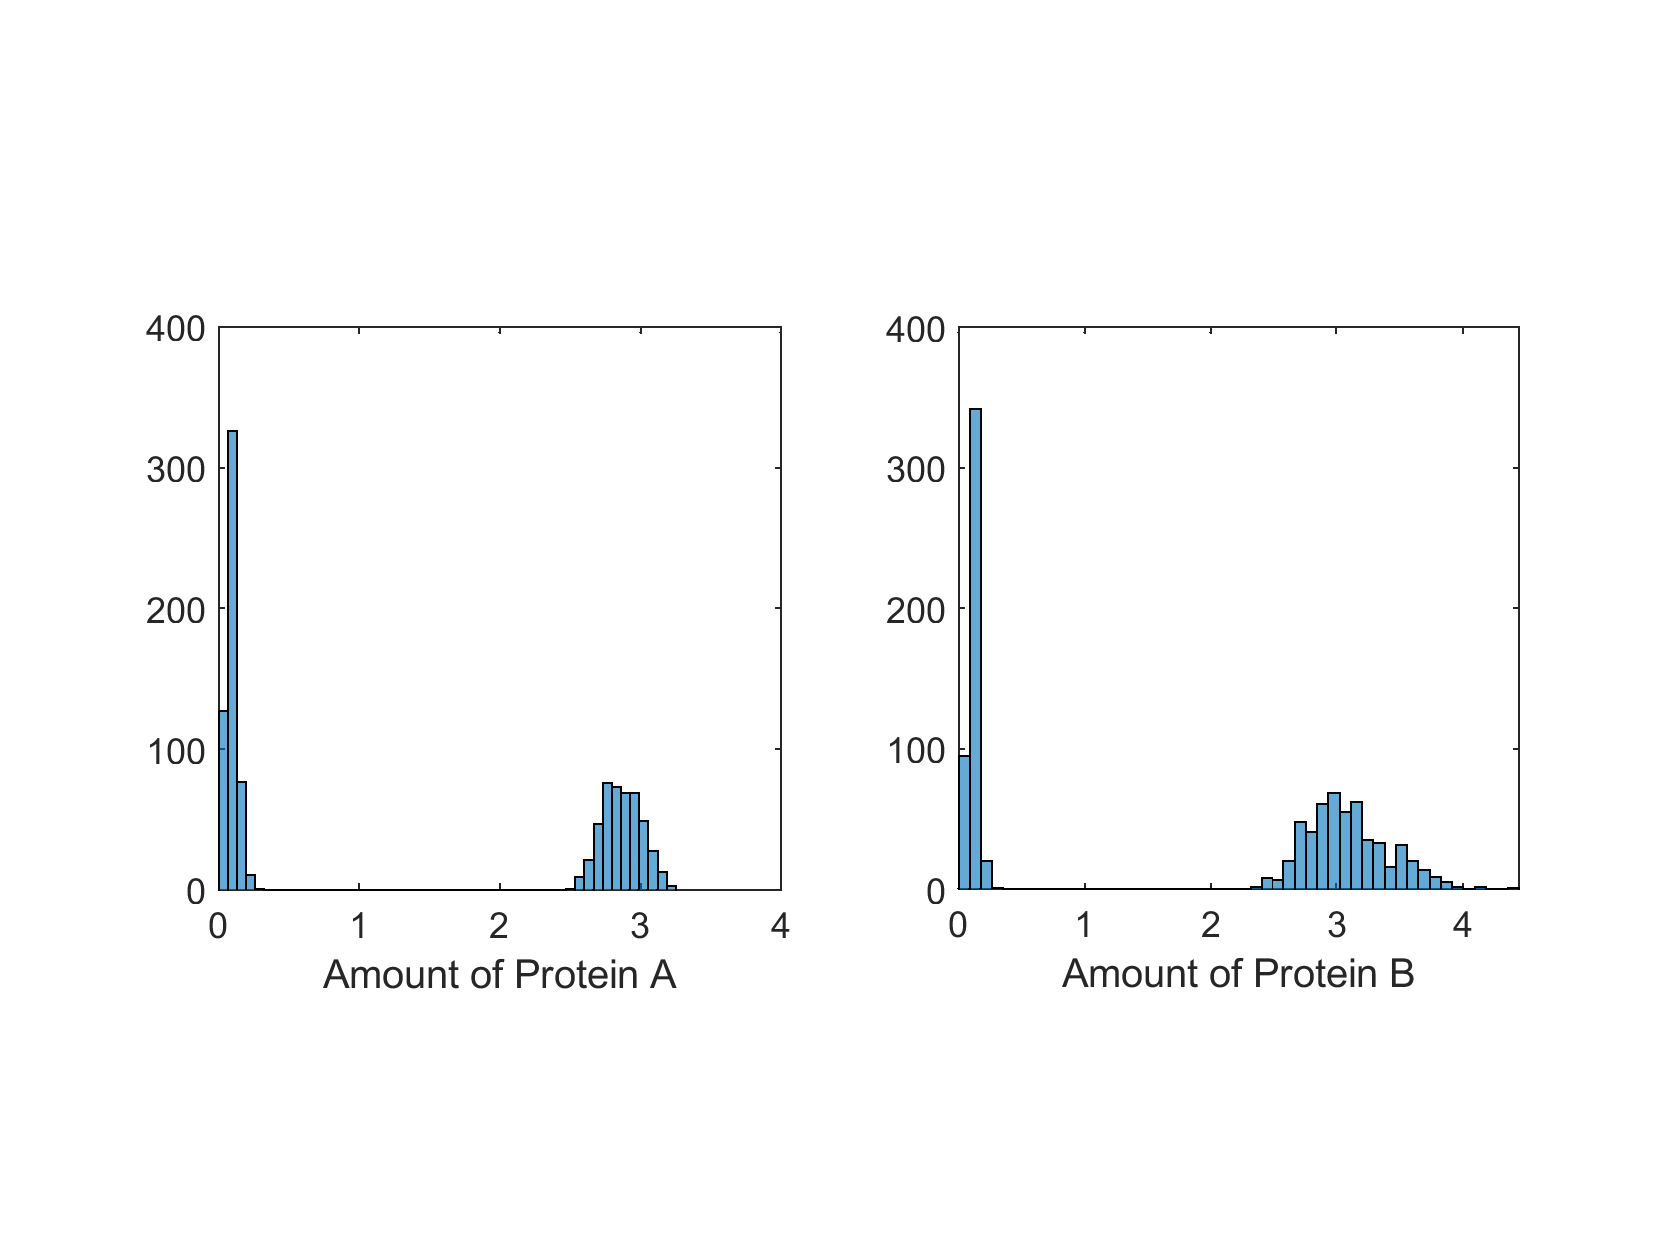


figure(); clf; 
subplot(1,2,1); hold on; box on;
axis square
histogram(storage_A, 50);
xlabel('Amount of Protein A')

subplot(1,2,2); hold on; box on;
axis square
histogram(storage_B,50);
xlabel('Amount of Protein B')

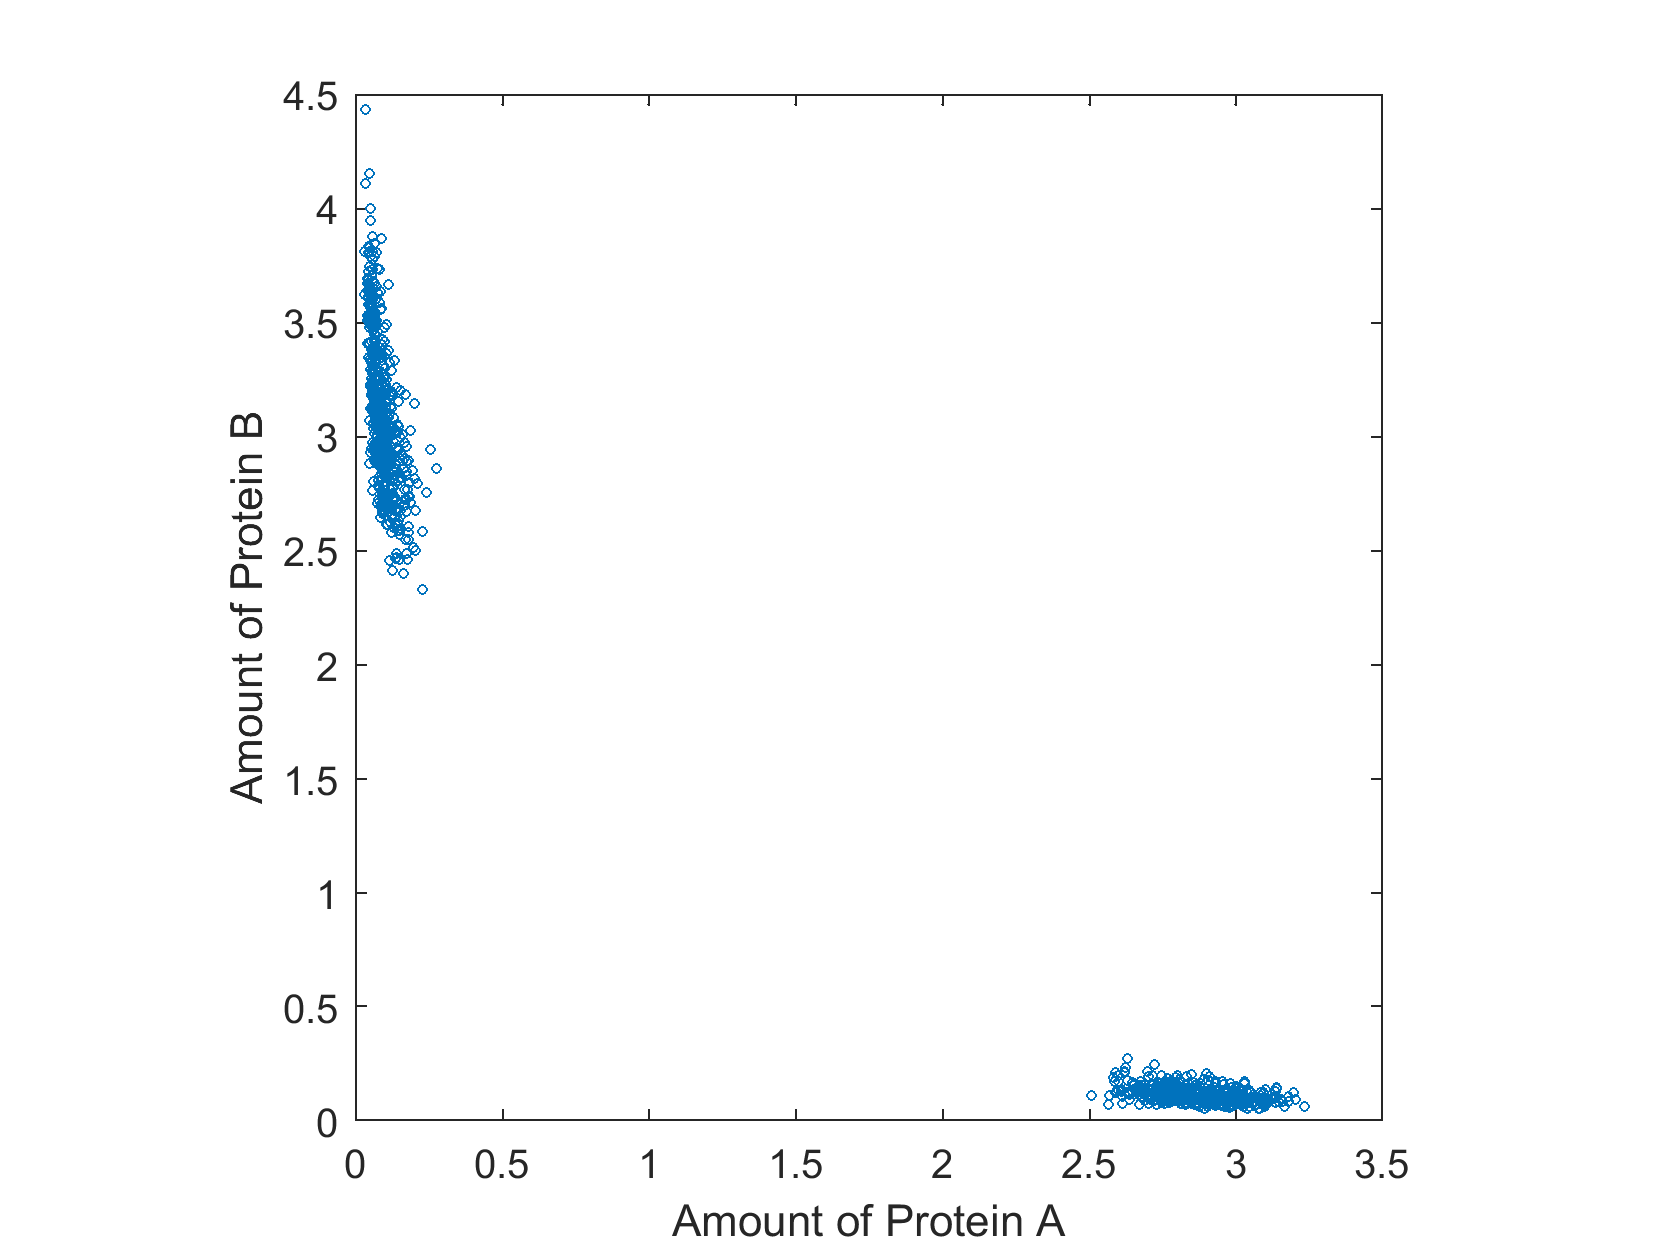


figure(); hold on; box on;
axis square
scatter(storage_A,storage_B,5);
xlabel('Amount of Protein A')
ylabel('Amount of Protein B')

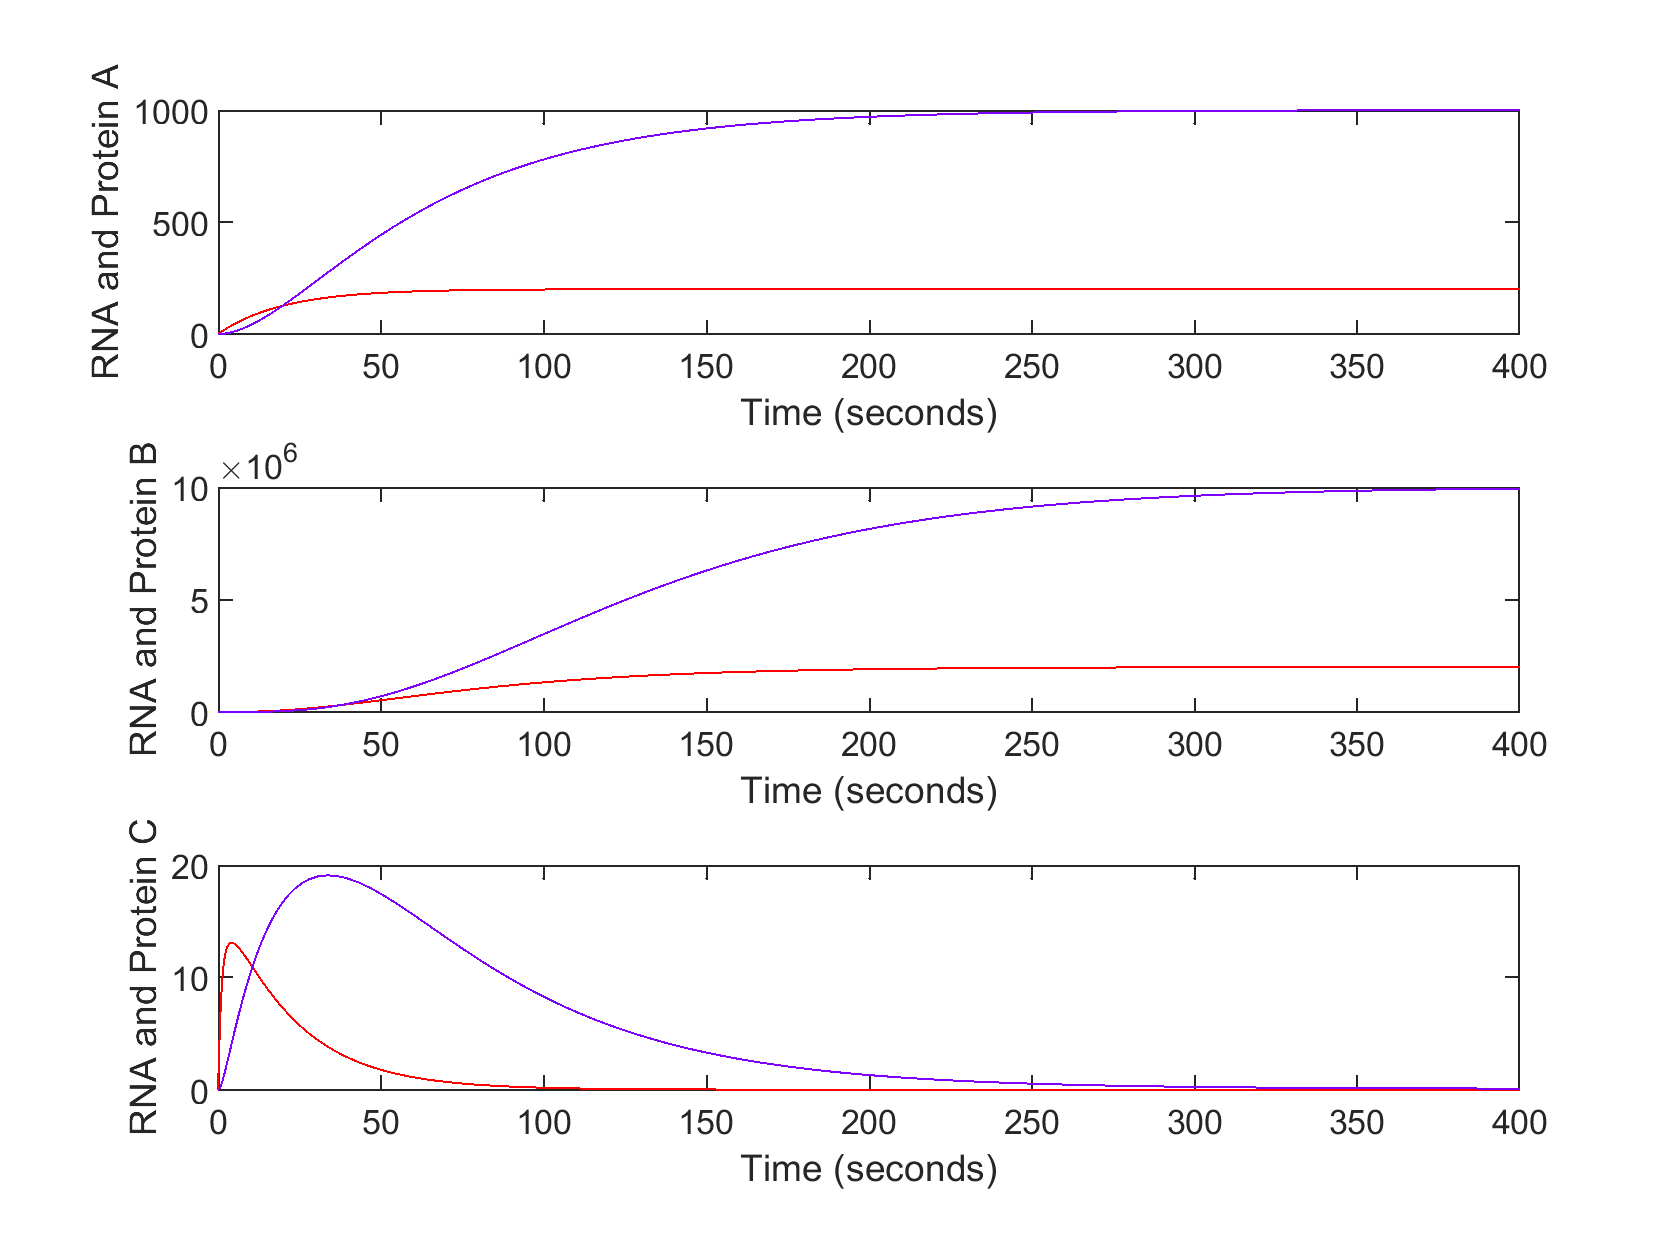

%% 6.0 ----- INCOHERENT FEED FORWARD -----

delta_ma = 0.05;
gamma_pa = 0.1;
delta_pa = 0.02;

delta_mb = 0.05;
gamma_pb = 0.1;
delta_pb = 0.02;

delta_mc = 0.05;
gamma_pc = 0.1;
delta_pc = 0.02;

gamma_ma = 10;

Kab = 10; % Strength (EC50) of activation of  by B 
gamma_mb =@(pa) 10.*(1+(Kab*pa));

Kac = 10;
Kbc = 10; % Strength (IC50) of inhibition of B by A 
gamma_mc =@(pa,pb) 10.*(1+(Kac*pa))./(1+Kbc*pb);

dmadt =@(ma,pa,mb,pb,mc,pc,t) +gamma_ma - delta_ma*ma;
dpadt =@(ma,pa,mb,pb,mc,pc,t) +gamma_pa*ma - delta_pa*pa;

dmbdt =@(ma,pa,mb,pb,mc,pc,t) +gamma_mb(pa) - delta_mb*mb;
dpbdt =@(ma,pa,mb,pb,mc,pc,t) +gamma_pb*mb - delta_pb*pb;

dmcdt =@(ma,pa,mb,pb,mc,pc,t) +gamma_mc(pa,pb) - delta_mc*mc;
dpcdt =@(ma,pa,mb,pb,mc,pc,t) +gamma_pc*mc - delta_pc*pc;


dxdt = @(t,x)[dmadt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dpadt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dmbdt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dpbdt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dmcdt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dpcdt(x(1),x(2),x(3),x(4),x(5),x(6),t)];

initialCondition = [0,0,0,0,0,0];
          
[T, X] = ode45(dxdt, [0.0,400], initialCondition);

figure(); clf; 
subplot(3,1,1);hold on; box on;
plot(T,X(:,1),'-r'); % red for RNA
plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple
ylabel('RNA and Protein A')
xlabel('Time (seconds)')

subplot(3,1,2);hold on; box on;
plot(T,X(:,3),'-r'); % red for RNA
plot(T,X(:,4),'-', 'color', [0.5 0 1]); % purple
ylabel('RNA and Protein B')
xlabel('Time (seconds)')

subplot(3,1,3);hold on; box on;
plot(T,X(:,5),'-r'); % red for RNA
plot(T,X(:,6),'-', 'color', [0.5 0 1]); % purple
ylabel('RNA and Protein C')
xlabel('Time (seconds)')

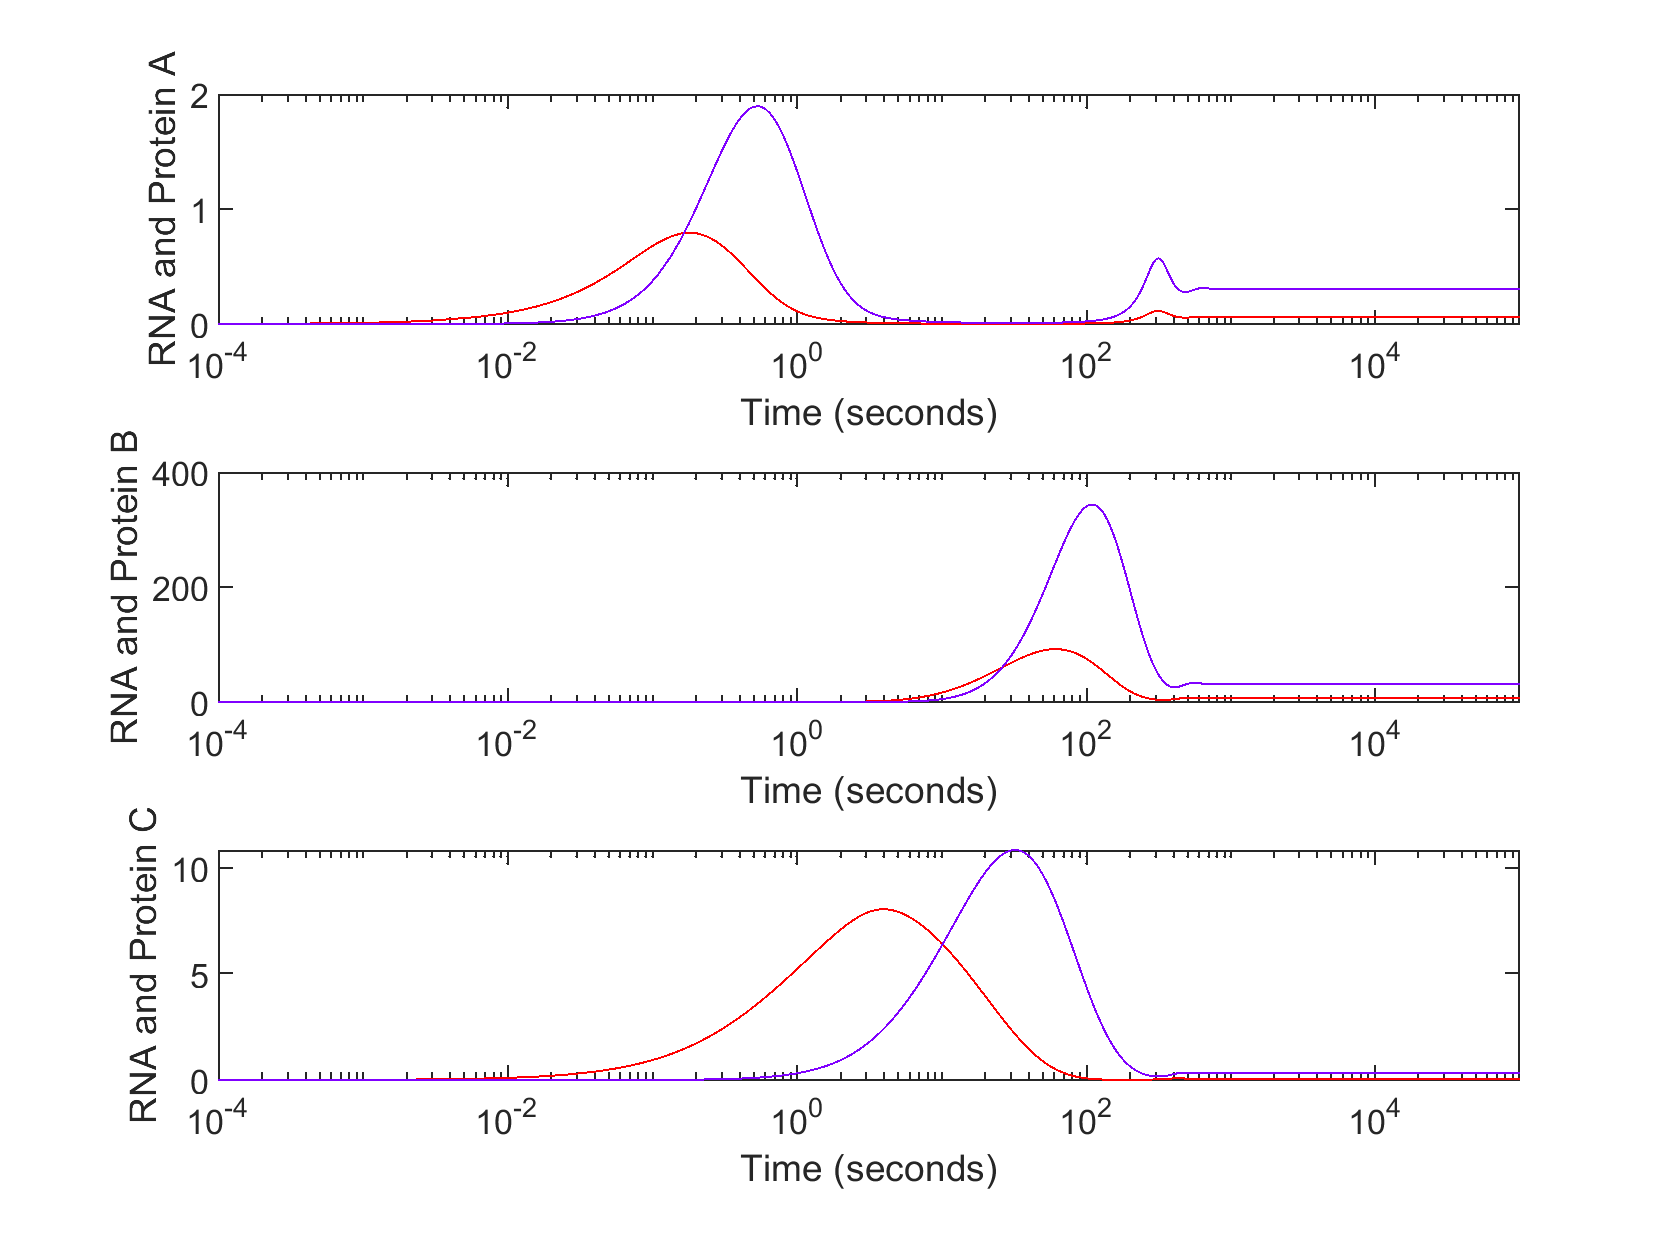

%% 7.0 ----- REPRESSILATOR -----

delta_ma = 100*0.05;
gamma_pa = 100*0.1;
delta_pa = 100*0.02;

delta_mb = 0.05;
gamma_pb = 0.1;
delta_pb = 0.02;

delta_mc = 0.05;
gamma_pc = 0.1;
delta_pc = 0.02;

Kca = 100; % Strength (IC50) of inhibition of  by B 
gamma_ma =@(pc) 10./(1+(Kca*pc));

Kab = 100; % Strength (IC50) of inhibition of B by A 
gamma_mb =@(pa) 10./(1+(Kab*pa));

Kbc = 100; % Strength (IC50) of inhibition of B by A 
gamma_mc =@(pb) 10./(1+(Kbc*pb));

dmadt =@(ma,pa,mb,pb,mc,pc,t) +gamma_ma(pc) - delta_ma*ma;
dpadt =@(ma,pa,mb,pb,mc,pc,t) +gamma_pa*ma - delta_pa*pa;

dmbdt =@(ma,pa,mb,pb,mc,pc,t) +gamma_mb(pa) - delta_mb*mb;
dpbdt =@(ma,pa,mb,pb,mc,pc,t) +gamma_pb*mb - delta_pb*pb;

dmcdt =@(ma,pa,mb,pb,mc,pc,t) +gamma_mc(pb) - delta_mc*mc;
dpcdt =@(ma,pa,mb,pb,mc,pc,t) +gamma_pc*mc - delta_pc*pc;


dxdt = @(t,x)[dmadt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dpadt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dmbdt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dpbdt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dmcdt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dpcdt(x(1),x(2),x(3),x(4),x(5),x(6),t)];

initialCondition = [0,0,0,0,0,0];
          
[T, X] = ode45(dxdt, [0,1e5], initialCondition);

figure(); clf; 
subplot(3,1,1);hold on; box on;
plot(T,X(:,1),'-r'); % red for RNA
plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple
ylabel('RNA and Protein A')
xlabel('Time (seconds)')
set(gca,'xscale','log','xlim',[1e-4,1e5])

subplot(3,1,2);hold on; box on;
plot(T,X(:,3),'-r'); % red for RNA
plot(T,X(:,4),'-', 'color', [0.5 0 1]); % purple
ylabel('RNA and Protein B')
xlabel('Time (seconds)')
set(gca,'xscale','log','xlim',[1e-4,1e5])


subplot(3,1,3);hold on; box on;
plot(T,X(:,5),'-r'); % red for RNA
plot(T,X(:,6),'-', 'color', [0.5 0 1]); % purple
ylabel('RNA and Protein C')
xlabel('Time (seconds)')
set(gca,'xscale','log','xlim',[1e-4,1e5])